cd Individual_masks
dc = dir('*.png');

names = {dc(:).name};

for k = 1 : length(names)
  fprintf('names{%d} = %s\n', k, names{k});
end

names{1} = 0.png
names{2} = 1.png
names{3} = 10.png
names{4} = 11.png
names{5} = 12.png
names{6} = 13.png
names{7} = 14.png
names{8} = 15.png
names{9} = 16.png
names{10} = 2.png
names{11} = 3.png
names{12} = 4.png
names{13} = 5.png
names{14} = 6.png
names{15} = 7.png
names{16} = 8.png
names{17} = 9.png



for img = dc
    mask = imread("img");
    imshow(mask);
end

Error using imread>get_full_filename (line 569)
File "img" does not exist.

Error in imread (line 371)
    fullname = get_full_filename(filename);


mask = imread("Individual_masks/10.png");
imshow(mask);


mask2 = im2bw(mask)

mask2 = 51×104 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0
   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   

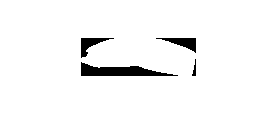

imshow(outline2)

outline = bwmorph(mask2, 'remove')

outline = 51×104 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0
   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

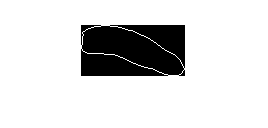

imshow(outline)

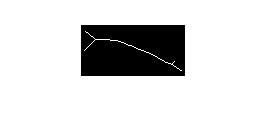

skeleton = bwmorph(mask2,'skel',Inf);
imshow(skeleton);

full = (skeleton + outline)

full =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     1     1     0     0     0     0     0

imwrite(full, 'my_closet/skel_10.png')